%{ 
Group 3:
1. Steve Vinsensius Jo - V01099466
2. Likkhith Krishnamurthy Aditya - V01098937
%}
clear all;

Task 1

Use the methods you created in Exercise 1 to create a 3-dimensional data set consisting of 5 Gaussian classes, with arbitrary means and covariances, with the following number of samples drawn from each class:

Class A: 750,000 samples; Class B: 190,000; Class C: 45,000; Class D: 12,000; Class E: 3,000.

Your data should be constructed such that all of the classes retain significant overlaps within one or two standard deviations of their means.

rng(537);
CLASS_NAMES = {'A', 'B', 'C', 'D', 'E'};
N_CLASS = [750000 190000 45000 12000 3000];
MU = {[0; 0; 0], [1.4; 1.1; 0.9], [1.2; -1.3; -1.0], [-1.1; 1.4; -1.2], [-1.3; -1.0; 1.5]};
SIGMA = {[4.0 1.2 0.6; 1.2 3.0 0.5; 0.6 0.5 2.5], ...
         [2.0 -0.5 0.3; -0.5 1.6 0.2; 0.3 0.2 1.2], ...
         [1.6 0.4 -0.3; 0.4 2.0 0.5; -0.3 0.5 1.4], ...
         [1.4 0.3 0.4; 0.3 1.2 -0.3; 0.4 -0.3 1.8], ...
         [1.2 0.3 0.2; 0.3 1.0 0.1; 0.2 0.1 0.9]};

N = sum(N_CLASS);
X = zeros(N, 3);
y = zeros(N, 1);
first = 1;
for k = 1:5
    rows = first:first + N_CLASS(k) - 1;
    [X(rows, :), genMean, genCov] = generateGaussian(MU{k}, SIGMA{k}, N_CLASS(k));
    y(rows) = k;
    first = first + N_CLASS(k);
    fprintf('Class %s: %6d samples, largest mean error %.1e, largest covariance error %.1e\n', CLASS_NAMES{k}, N_CLASS(k), max(abs(genMean(:) - MU{k})), max(abs(genCov(:) - SIGMA{k}(:))));
end

Class A: 750000 samples, largest mean error 3.1e-17, largest covariance error 9.3e-15
Class B: 190000 samples, largest mean error 0.0e+00, largest covariance error 2.7e-15
Class C:  45000 samples, largest mean error 1.3e-15, largest covariance error 1.8e-15
Class D:  12000 samples, largest mean error 1.8e-15, largest covariance error 1.6e-15
Class E:   3000 samples, largest mean error 6.7e-16, largest covariance error 2.0e-15



overlap2 = zeros(5);
for i = 1:5
    for j = 1:5
        Dij = X(y == j, :) - MU{i}';
        overlap2(i, j) = 100*mean(sum((Dij / SIGMA{i}) .* Dij, 2) <= 4);
    end
end
fprintf('\nPercentage of each class (columns) within 2 standard deviations of each class mean (rows):\n');


Percentage of each class (columns) within 2 standard deviations of each class mean (rows):


fprintf('        A       B       C       D       E\n');

        A       B       C       D       E


for i = 1:5
    fprintf('%s %7.1f %7.1f %7.1f %7.1f %7.1f\n', CLASS_NAMES{i}, overlap2(i, :));
end

A    73.9    81.2    66.3    65.4    76.1
B    30.2    73.8    20.7    20.2     7.1
C    26.8    23.1    73.7     4.9     8.4
D    21.0    17.7     4.5    74.0     7.3
E    13.9     3.4     4.6     4.8    74.2


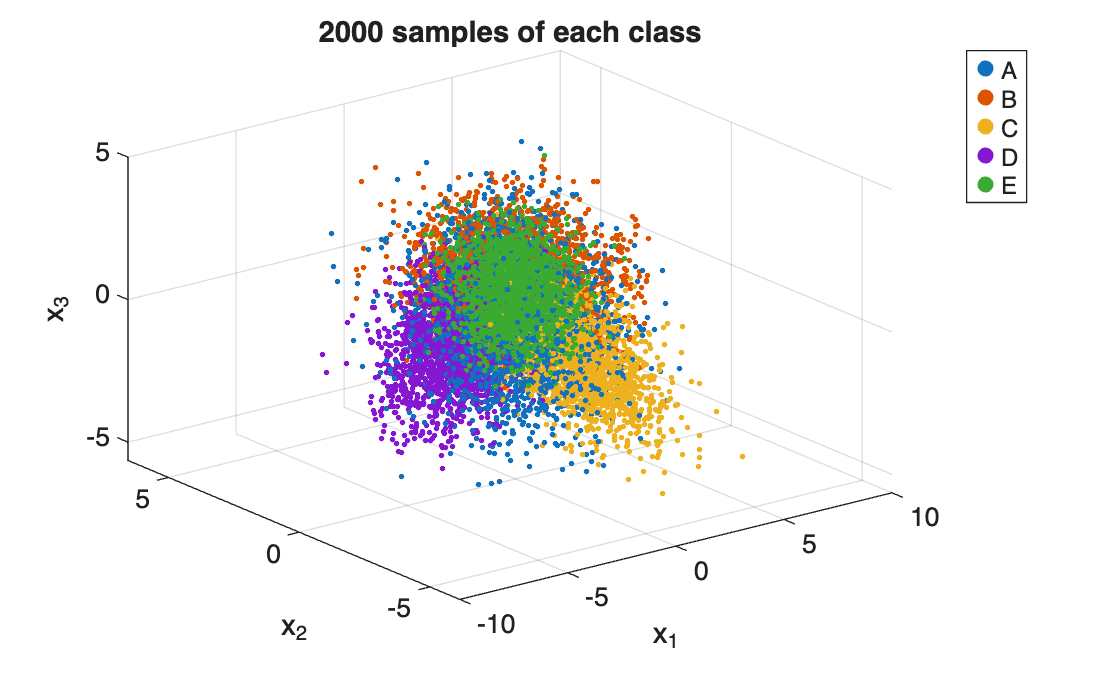


figure
hold on
for k = 1:5
    idx = find(y == k);
    idx = idx(1:min(2000, numel(idx)));
    scatter3(X(idx, 1), X(idx, 2), X(idx, 3), 4, 'filled')
end
hold off
xlabel('x_1'), ylabel('x_2'), zlabel('x_3'), grid on, view(3)
legend(CLASS_NAMES), title('2000 samples of each class')

The five classes are constructed using our Exercise 1 function, generateGaussian (whitening followed by inverse whitening), so each class has its specified mean and covariance precisely; the printed errors are at round-off level. Class A is at the origin with maximum spread, while the other four classes are around it, about 2 units from A’s mean, which is one standard deviation of A.

The overlap matrix proves the requirement of overlap. Approximately 65% to 81% of each small class is within two standard deviations of class A’s mean (74% of a 3-D Gaussian distribution is within two standard deviations of its mean), and all classes have at least about 3% of their samples within two standard deviations of the mean of all other classes. We plotted only 2,000 samples for each class, as it would be very slow to plot all one million points.

Task 2

Construct randomly (uniformly) selected training and test data set from the composite of your constructed 5 class data sets, where the training data should constitute 10% of the overall data and the test data the remaining 90% of the data. Record the number of train data samples for each of the training set classes as well as the exact indexes of the training and test data samples.

rng(2);
TRAIN_FRACTION = 0.10;
perm = randperm(N);
nTrain = round(TRAIN_FRACTION*N);
trainIdx = sort(perm(1:nTrain))';
testIdx  = sort(perm(nTrain+1:end))';
idxTrain = uint32(trainIdx);
idxTest  = uint32(testIdx);
save('Exercise5_indices.mat', 'idxTrain', 'idxTest', '-v7');

Xtr = X(trainIdx, :);   ytr = y(trainIdx);
Xte = X(testIdx, :);    yte = y(testIdx);
trainCounts = accumarray(ytr, 1, [5 1])';
testCounts  = accumarray(yte, 1, [5 1])';

fprintf('Training set: %d samples (%.0f%%), test set: %d samples; overlap between them: %d\n', nTrain, 100*nTrain/N, numel(testIdx), numel(intersect(trainIdx, testIdx)));

Training set: 100000 samples (10%), test set: 900000 samples; overlap between them: 0


fprintf('First training indices: %s\n', mat2str(trainIdx(1:8)'));

First training indices: [2 20 22 24 52 56 58 68]


fprintf('Class   total   training   10%% of total   test\n');

Class   total   training   10% of total   test


for k = 1:5
    fprintf('  %s   %6d   %8d   %12.0f   %6d\n', CLASS_NAMES{k}, N_CLASS(k), trainCounts(k), TRAIN_FRACTION*N_CLASS(k), testCounts(k));
end

  A   750000      74885          75000   675115
  B   190000      19089          19000   170911
  C    45000       4511           4500    40489
  D    12000       1224           1200    10776
  E     3000        291            300     2709


A uniform random permutation of all 1,000,000 samples is created using randperm. The first 100,000 samples (10%) become the training data set while the rest (90%) become the test data set, without any overlap between them. The specific indexes used are stored in Exercise5_indices.mat (idxTrain and idxTest), whereas the table shows how many samples of each class have been included in the training data set. Since the sampling process does not consider the classes, their sizes approximate to 10% of each class (Task 6 determines how far from 10%). Class E has approximately 300 training samples compared to 75,000 of class A.

Task 3

Use the training data sets to build and a Bayes and neural network classifier for this data.

bayes = fitBayes(Xtr, ytr);
fprintf('Priors estimated from the training set: %s\n', mat2str(round(bayes.prior, 4)));

Priors estimated from the training set: [0.7489 0.1909 0.0451 0.0122 0.0029]



[net, tr] = trainNet(Xtr, ytr, 3);
fprintf('Network training stopped after %d epochs (%s)\n', tr.num_epochs, tr.stop);

Network training stopped after 172 epochs (Training finished: Met validation criterion)


Bayes classifier is a parametric classifier that calculates for each class the mean vector, covariance matrix, and prior (proportion of the training data belonging to the class). Then it classifies data into classes whose discriminant g_k(x) = -0.5*(x - mu_k)'*inv(Sigma_k)*(x - mu_k) - 0.5*log(det(Sigma_k)) + log(P_k) is maximal, where we use the discriminant function from our Exercise 1. Priors match the class imbalance, going from 0.75 for A down to 0.003 for E.

Our neural network is created in code with patternnet(10), the same default network that nnstart’s Pattern Recognition app builds: 3 inputs, 10 tansig hidden neurons, and 5 softmax output neurons. The network is trained with scaled conjugate gradient on the cross-entropy of the training set, 85% of which trains the weights and 15% validates them.

Task 4

Apply the testing data to assess the performance of your constructed classifiers against each of the 5 classes. Explain why the classification performance is (or is not) consistent across each of Class A through E.

yhat_bayes = bayesClassify(bayes, Xte);
yhat_nn    = netClassify(net, Xte);

trueModel = struct('mu', {MU}, 'Sigma', {SIGMA}, 'prior', N_CLASS/N);
yhat_true = bayesClassify(trueModel, Xte);

rec_bayes = perClassRecall(yte, yhat_bayes);
rec_nn    = perClassRecall(yte, yhat_nn);
rec_true  = perClassRecall(yte, yhat_true);
fprintf('Test set: percentage of each class classified correctly\n');

Test set: percentage of each class classified correctly


fprintf('Class   test samples   Bayes   network   Bayes with true parameters\n');

Class   test samples   Bayes   network   Bayes with true parameters


for k = 1:5
    fprintf('  %s   %12d   %5.1f   %7.1f   %5.1f\n', CLASS_NAMES{k}, testCounts(k), rec_bayes(k), rec_nn(k), rec_true(k));
end

  A         675115    93.2      92.9    93.5
  B         170911    29.3      30.4    27.9
  C          40489    11.3       9.7    11.4
  D          10776     1.3       0.9     1.8
  E           2709     0.0       0.0     0.0


fprintf('Overall accuracy:  Bayes %.2f%%, network %.2f%%, true-parameter Bayes %.2f%%\n', 100*mean(yhat_bayes == yte), 100*mean(yhat_nn == yte), 100*mean(yhat_true == yte));

Overall accuracy:  Bayes 75.97%, network 75.91%, true-parameter Bayes 75.98%


fprintf('Mean of the per-class rates (balanced accuracy): Bayes %.1f%%, network %.1f%%\n', mean(rec_bayes), mean(rec_nn));

Mean of the per-class rates (balanced accuracy): Bayes 27.0%, network 26.8%



fprintf('\nBayes confusion matrix (rows: true class, columns: predicted class)\n');


Bayes confusion matrix (rows: true class, columns: predicted class)


printConfusion(yte, yhat_bayes, CLASS_NAMES);

              A         B         C         D         E
  A      629073     42927      3013       102         0
  B      120875     49993        43         0         0
  C       35382       537      4570         0         0
  D       10500       139         0       137         0
  E        2703         6         0         0         0


fprintf('Network confusion matrix (rows: true class, columns: predicted class)\n');

Network confusion matrix (rows: true class, columns: predicted class)


printConfusion(yte, yhat_nn, CLASS_NAMES);

              A         B         C         D         E
  A      627244     45366      2422        83         0
  B      118914     51971        25         1         0
  C       35997       578      3914         0         0
  D       10514       165         0        97         0
  E        2703         6         0         0         0



Cb = accumarray([yte, yhat_bayes], 1, [5 5]);
Cn = accumarray([yte, yhat_nn],    1, [5 5]);
prec_bayes = 100*diag(Cb)'./sum(Cb, 1);   % NaN when a class is never predicted
prec_nn    = 100*diag(Cn)'./sum(Cn, 1);
f1 = @(P, R) 2*P.*R./(P + R);
fprintf('Class   Bayes precision   Bayes F1   network precision   network F1\n');

Class   Bayes precision   Bayes F1   network precision   network F1


for k = 1:5
    fprintf('  %s   %15.1f   %8.1f   %17.1f   %10.1f\n', CLASS_NAMES{k}, prec_bayes(k), f1(prec_bayes(k), rec_bayes(k)), prec_nn(k), f1(prec_nn(k), rec_nn(k)));
end

  A              78.8       85.4                78.9         85.3
  B              53.4       37.8                53.0         38.6
  C              59.9       19.0                61.5         16.7
  D              57.3        2.5                53.6          1.8
  E               NaN        NaN                 NaN          NaN


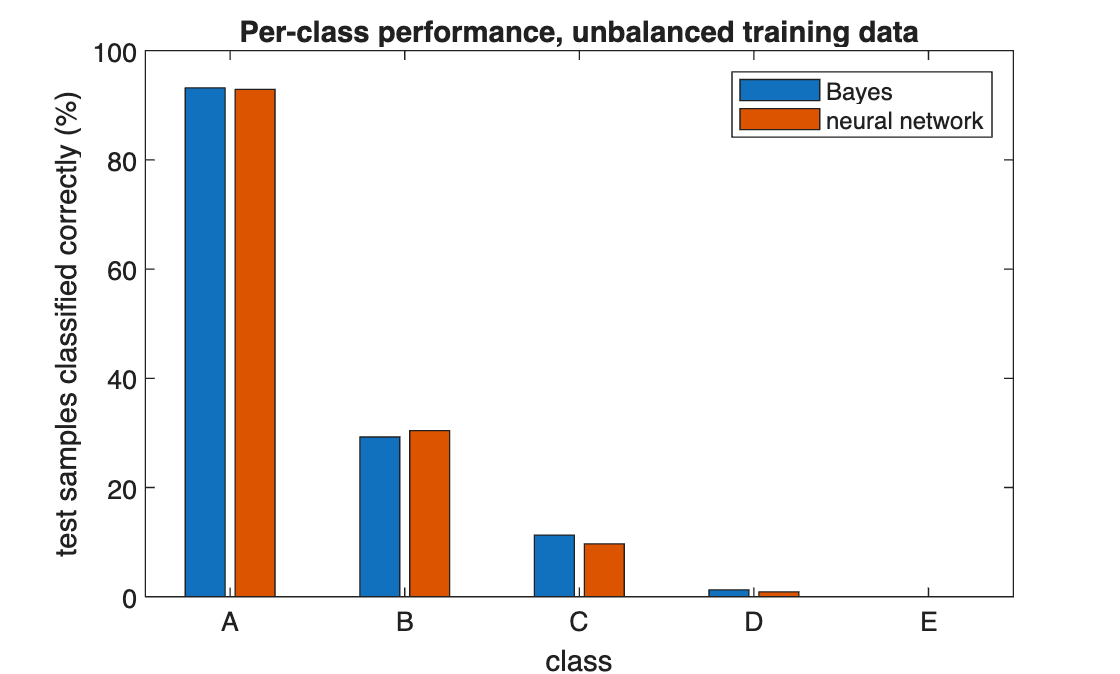


figure
bar([rec_bayes; rec_nn]')
set(gca, 'XTickLabel', CLASS_NAMES)
xlabel('class'), ylabel('test samples classified correctly (%)'), ylim([0 100])
legend('Bayes', 'neural network'), title('Per-class performance, unbalanced training data')

The accuracy of the classification is not uniform for all the classes. Both the classifiers are able to classify class A correctly 93% of the time, but class B is classified correctly around 28%, class C correctly around 11%, D almost never, and class E not at all (class E does not even occur in the confusion matrix). This is hidden by the overall accuracy of around 76%, as it is highly influenced by class A, which constitutes 75% of the dataset.

This is not because of any inadequacy in the training procedure; the Bayes classifier that uses true values of means, covariances, and priors gives very similar results. Bayes decision rule selects the class with maximum prior probability times likelihood. In case of overlapping classes, the prior of A is 250 times greater than that of E (0.75 versus 0.003), which means that A wins almost everywhere, including even areas close to the centers of the smaller classes. A smaller class can win only when its density is much greater than that of A, but due to strong overlap of the classes this almost never occurs. The classifier minimizes the overall number of mistakes, and therefore the neglect of the rare classes entails a relatively small number of mistakes overall. The same is true for the neural network, since it also minimizes the cross-entropy on unbalanced data sets, producing similar posterior probabilities.

Precision gives a second view of the same bias. When the classifiers do predict one of the minority classes, they are right more than half the time (53–62% for classes B, C and D), but they almost never predict them, which leads to very poor recall and F1 scores. Precision for class E is undefined, since neither classifier ever predicts it.

Task 5

Discuss the similarities and differences that the unbalanced data sets have on the in sensitivity and robustness of your constructed classifiers and their training versus test set performances. Which types of classification approaches are more robust to unbalanced data sets (and why?) neural network type approaches, i.e., non-parametric approaches or Bayes-like approaches, i.e., parametric approaches?

rec_bayes_tr = perClassRecall(ytr, bayesClassify(bayes, Xtr));
rec_nn_tr    = perClassRecall(ytr, netClassify(net, Xtr));
fprintf('Percentage classified correctly, training vs test\n');

Percentage classified correctly, training vs test


fprintf('Class   training samples   Bayes train   Bayes test   network train   network test\n');

Class   training samples   Bayes train   Bayes test   network train   network test


for k = 1:5
    fprintf('  %s   %16d   %11.1f   %10.1f   %13.1f   %12.1f\n', CLASS_NAMES{k}, trainCounts(k), rec_bayes_tr(k), rec_bayes(k), rec_nn_tr(k), rec_nn(k));
end

  A              74885          93.1         93.2            92.9           92.9
  B              19089          29.7         29.3            30.7           30.4
  C               4511          10.7         11.3             9.4            9.7
  D               1224           1.4          1.3             0.7            0.9
  E                291           0.0          0.0             0.0            0.0



fprintf('Largest error of the estimated parameters: ');

Largest error of the estimated parameters: 

for k = 1:5
    fprintf('%s mean %.3f, cov %.3f;  ', CLASS_NAMES{k}, max(abs(bayes.mu{k} - MU{k})), max(max(abs(bayes.Sigma{k} - SIGMA{k}))));
end

A mean 0.003, cov 0.044;  B mean 0.018, cov 0.016;  C mean 0.013, cov 0.040;  D mean 0.067, cov 0.078;  E mean 0.086, cov 0.263;  

fprintf('\n');

Similarities: in both classifiers, the training and test rates are nearly identical for all classes, and both exhibit high sensitivity for class A and very low sensitivity for the small classes. For the Bayes classifier, 9 parameters plus a prior are needed for each class, and even for class E, where there are 300 or so training examples for the estimation, these estimates work pretty well (as seen from the parameter errors above, they increase as the size of the class decreases, but still remain small). For the neural network, only 95 weights are used, together with 100,000 training samples, thus overfitting is not an issue here either.

Differences and Robustness: Parametric and Bayesian classifiers are more robust when data is unbalanced provided the model used (Gaussian distribution in our case) is correct. They fit separate models for each class, thus preventing a model of a small class from being overridden by a model of the large class and requiring only a few number of parameters for each class. Imbalance affects only priors that are explicitly specified and, therefore, it is easy to compensate for the imbalance post-processing by adjusting priors or costs (Task 8). Neural network and other non-parametric methods learn boundary between classes directly from examples. Loss function for these methods is defined as a sum over training examples. Thus 75% of loss function corresponds to class A and only 0.3% to class E, and other classes have practically no effect on boundary positioning. Non-parametric methods require many examples of each class to define boundary and, therefore, rely on few examples for classification of small classes while class priors are embedded into weights.

Task 6

Discuss the impacts that selecting random draws from unbalanced data sets can have on the composition of the resulting training data set(s). For each class, what will be the expected number of samples from the class drawn into the training data set and compute the probability of this occurring? How many possible draws from class E into the training set can occur with a probability of 99%? Compute how the range of possible draws changes as the size of class E is increased or decreased?

Hints: Which probability distribution could you use to model the likelihood(s) of drawing samples into the training set? How many standard deviations of this distribution are required to cover 99% of outcomes?, i.e., fall into a 99% confidence interval.

p = TRAIN_FRACTION;
z99 = sqrt(2)*erfinv(0.99);
expected = p*N_CLASS;
sd = sqrt(N_CLASS*p*(1 - p));
pExact = exp(binoLogPmf(expected, N_CLASS, p));
lo = ceil(expected - z99*sd);
hi = floor(expected + z99*sd);
fprintf('Training count of each class ~ Binomial(N_k, %.2f); 99%% range = expected +- %.3f sd\n', p, z99);

Training count of each class ~ Binomial(N_k, 0.10); 99% range = expected +- 2.576 sd


fprintf('Class   N_k      expected   sd      P(exactly expected)   99%% range        counts in range   actual\n');

Class   N_k      expected   sd      P(exactly expected)   99% range        counts in range   actual


for k = 1:5
    fprintf('  %s   %6d   %8.0f   %6.1f   %19.5f   [%6d, %6d]   %15d   %6d\n', CLASS_NAMES{k}, N_CLASS(k), expected(k), sd(k), pExact(k), lo(k), hi(k), hi(k) - lo(k) + 1, trainCounts(k));
end

  A   750000      75000    259.8               0.00154   [ 74331,  75669]              1339    74885
  B   190000      19000    130.8               0.00305   [ 18664,  19336]               673    19089
  C    45000       4500     63.6               0.00627   [  4337,   4663]               327     4511
  D    12000       1200     32.9               0.01214   [  1116,   1284]               169     1224
  E     3000        300     16.4               0.02427   [   258,    342]                85      291



nE = N_CLASS(5);
cdfE = cumsum(exp(binoLogPmf(0:nE, nE, p)));
loE = find(cdfE >= 0.005, 1) - 1;
hiE = find(cdfE >= 0.995, 1) - 1;
fprintf('Class E, exact binomial 99%% range: [%d, %d], %d possible counts, probability %.4f\n', loE, hiE, hiE - loE + 1, cdfE(hiE + 1) - cdfE(loE));

Class E, exact binomial 99% range: [258, 343], 86 possible counts, probability 0.9912




fprintf('\nSize of class E   expected   99%% range          counts in range   +- percent of expected\n');


Size of class E   expected   99% range          counts in range   +- percent of expected


for nE = [300 1000 3000 10000 30000 100000]
    e = p*nE;
    s = sqrt(nE*p*(1 - p));
    fprintf('%16d   %8.0f   [%6d, %6d]   %15d   %21.1f\n', nE, e, ceil(e - z99*s), floor(e + z99*s), floor(e + z99*s) - ceil(e - z99*s) + 1, 100*z99*s/e);
end

             300         30   [    17,     43]                27                    44.6
            1000        100   [    76,    124]                49                    24.4
            3000        300   [   258,    342]                85                    14.1
           10000       1000   [   923,   1077]               155                     7.7
           30000       3000   [  2867,   3133]               267                     4.5
          100000      10000   [  9756,  10244]               489                     2.4


fprintf('A class of only 30 samples would be missing from the training set with probability %.3f\n', (1 - p)^30);

A class of only 30 samples would be missing from the training set with probability 0.042


Each training example is chosen independently and uniformly at random, irrespective of its class; hence, the number of training examples of class k follows a binomial distribution, Binomial(N_k, 0.1), with mean 0.1*N_k and standard deviation sqrt(N_k*0.1*0.9). (Strictly, because exactly 100,000 samples are drawn without replacement, the count follows a hypergeometric distribution. The variance of such a distribution is lower than that of a binomial by a factor of roughly (1 − N_k/N). This is insignificant for the small classes (0.997 for E, 0.988 for D, 0.955 for C), but for B it is 0.81 and for A just 0.25. Therefore, the actual deviation of A is about 130, not 260 as computed below, and its 99% interval is half as wide. For class E, which is the class mentioned in the question, the answer based on the binomial distribution is essentially correct.) These means are 75,000, 19,000, 4,500, 1,200 and 300. The probability of having exactly the mean is low; it is only about 0.15% for class A, increasing to about 2.4% for class E. So a randomly chosen training set rarely includes 10% of each class.

99% of normally distributed data lies within 2.576 standard deviations of the mean. In the case of class E, the standard deviation is 16.4, meaning that 99% of possible values will be between 258 and 342 class E samples in the training set: 85 possible values, ranging from about 14% under to 14% over the mean of 300 samples (the binomial distribution is from 258 to 343). The range becomes wider with the square root of the size of the class, but the range itself becomes smaller in proportion to the expected number of samples as 1/sqrt(N_E); for example, in the case of a class E of 300 samples, the range is from 17 to 43 samples (±45%), for 3,000 it is ±14%, and for 100,000 it is only ±2.4%. Thus, small classes are less likely to be represented correctly in a random selection, and very small classes may even not appear at all: a class of 30 samples will have zero training samples in 4% of cases.

Task 7

Compare the performance of your classifiers to a second set of classifiers constructed from balanced training data, i.e., generate balanced per-class data sets and retrain your classifiers.

rng(7);
N_BAL = 200000;
Xb = zeros(5*N_BAL, 3);
yb = zeros(5*N_BAL, 1);
for k = 1:5
    rows = (k - 1)*N_BAL + (1:N_BAL);
    Xb(rows, :) = generateGaussian(MU{k}, SIGMA{k}, N_BAL);
    yb(rows) = k;
end
permB = randperm(5*N_BAL);
trainIdxB = sort(permB(1:nTrain))';
Xtrb = Xb(trainIdxB, :);   ytrb = yb(trainIdxB);
fprintf('Balanced training set: %s samples per class\n', mat2str(accumarray(ytrb, 1, [5 1])'));

Balanced training set: [19883 19963 20240 19812 20102] samples per class



bayesB = fitBayes(Xtrb, ytrb);
[netB, trB] = trainNet(Xtrb, ytrb, 3);
fprintf('Network training stopped after %d epochs (%s)\n', trB.num_epochs, trB.stop);

Network training stopped after 190 epochs (Training finished: Met validation criterion)



yhat_bayesB = bayesClassify(bayesB, Xte);
yhat_nnB    = netClassify(netB, Xte);
rec_bayesB = perClassRecall(yte, yhat_bayesB);
rec_nnB    = perClassRecall(yte, yhat_nnB);
fprintf('Test set: percentage of each class classified correctly\n');

Test set: percentage of each class classified correctly


fprintf('Class   Bayes (unbalanced)   Bayes (balanced)   network (unbalanced)   network (balanced)\n');

Class   Bayes (unbalanced)   Bayes (balanced)   network (unbalanced)   network (balanced)


for k = 1:5
    fprintf('  %s   %18.1f   %16.1f   %20.1f   %18.1f\n', CLASS_NAMES{k}, rec_bayes(k), rec_bayesB(k), rec_nn(k), rec_nnB(k));
end

  A                 93.2               19.4                   92.9                 18.3
  B                 29.3               75.8                   30.4                 75.9
  C                 11.3               78.0                    9.7                 78.2
  D                  1.3               80.0                    0.9                 80.1
  E                  0.0               88.8                    0.0                 88.7


fprintf('Overall accuracy:  %18.2f   %16.2f   %20.2f   %18.2f\n', 100*mean(yhat_bayes == yte), 100*mean(yhat_bayesB == yte), 100*mean(yhat_nn == yte), 100*mean(yhat_nnB == yte));

Overall accuracy:               75.97              33.69                  75.91                32.86


fprintf('Balanced accuracy: %18.1f   %16.1f   %20.1f   %18.1f\n', mean(rec_bayes), mean(rec_bayesB), mean(rec_nn), mean(rec_nnB));

Balanced accuracy:               27.0               68.4                   26.8                 68.2


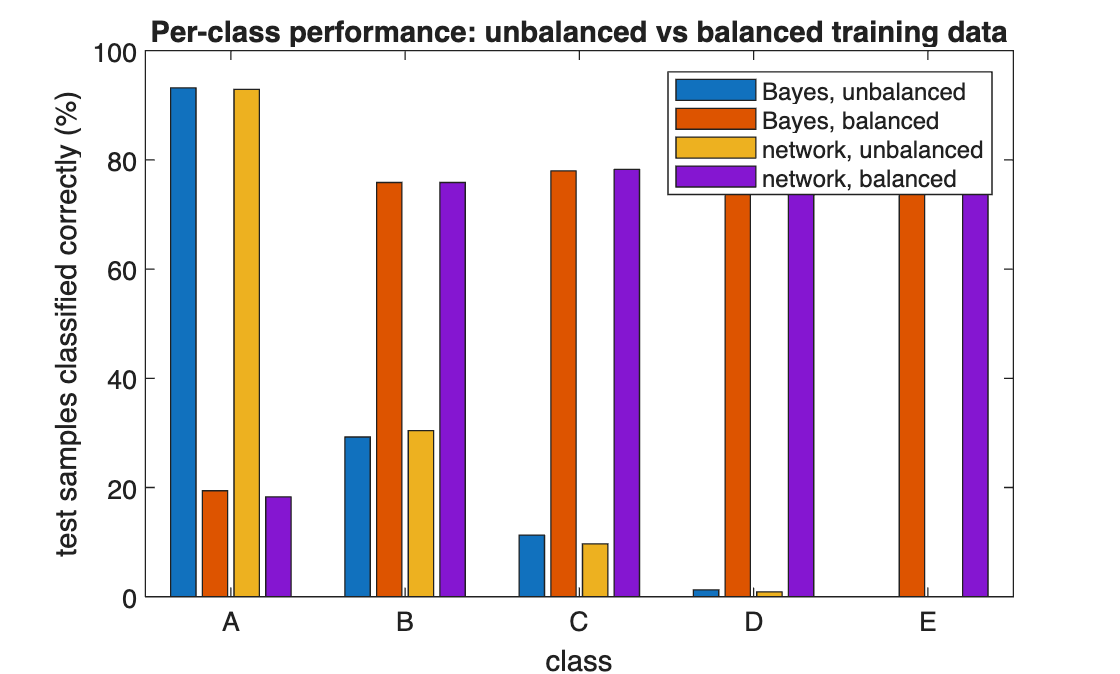


figure
bar([rec_bayes; rec_bayesB; rec_nn; rec_nnB]')
set(gca, 'XTickLabel', CLASS_NAMES)
xlabel('class'), ylabel('test samples classified correctly (%)'), ylim([0 100])
legend('Bayes, unbalanced', 'Bayes, balanced', 'network, unbalanced', 'network, balanced')
title('Per-class performance: unbalanced vs balanced training data')

For the balanced comparison we generated 200,000 samples of each class (the same total of 1,000,000) with the same means and covariances, took a random 10% as the training set (about 20,000 per class) and retrained both classifiers. Both pairs of classifiers are evaluated on the same original test set.

The balanced classifiers provide a much more balanced treatment of the classes: classes B through E are now identified between 76% and 89% of the time, and the balanced accuracy increases from roughly 27% to roughly 68%. Class A is identified only 19%, down from about 93%. This is the most diffuse class, overlapping with all other four, which means that in the scenario of balanced priors the more concentrated classes will prevail in most of the space near the mean of class A. With 75% of class A samples in the original test set, the accuracy decreases to 33% from roughly 76%. The Bayes classifier and the network are in close agreement, since both operate under conditions of balanced priors.

Neither is superior to the other. Training with the unbalanced data results in the least number of errors when the frequencies in reality coincide with that in the training data, whereas training with balanced data provides equal chances for all the classes, which is relevant if the rare classes (e.g., attacks or faults) are important. The decision depends on the cost of different errors.

Task 8

Unbalanced data sets occur commonly in real-world data analysis problems e.g., in cyber-security normal network traffic events typically outnumber malicious events by many orders of magnitude.

Discuss some of the possible approaches that could be applied to address the problem of unbalanced data. In general, there are three core approaches to addressing unbalanced data. Your discussion should include a detailed explanation of the pros and cons of each potential solution approach.

Note, in general, it may not be possible or feasible to simply collect sufficient data from each representative data class such that the training data with high likelihood is sufficiently balanced. Many real-world problems exist where data is innately unbalanced due to the nature of the problems space, e.g., medical diagnostics, faculty detection, cyber-security, etc.

bayesEq = bayes;
bayesEq.prior = ones(1, 5)/5;
yhat_bayesEq = bayesClassify(bayesEq, Xte);
Pnn = net(Xte')';
[~, yhat_nnEq] = max(Pnn ./ bayes.prior, [], 2);
fprintf('Test set, percentage classified correctly (classifiers trained on the UNBALANCED data)\n');

Test set, percentage classified correctly (classifiers trained on the UNBALANCED data)


fprintf('Class   Bayes, equal priors   network, outputs divided by priors\n');

Class   Bayes, equal priors   network, outputs divided by priors


rec_bayesEq = perClassRecall(yte, yhat_bayesEq);
rec_nnEq    = perClassRecall(yte, yhat_nnEq);
for k = 1:5
    fprintf('  %s   %19.1f   %34.1f\n', CLASS_NAMES{k}, rec_bayesEq(k), rec_nnEq(k));
end

  A                  19.4                                 18.3
  B                  74.8                                 75.0
  C                  78.1                                 77.7
  D                  80.6                                 79.7
  E                  89.1                                 86.1


fprintf('Balanced accuracy: %.1f%% and %.1f%% (balanced training data in Task 7: %.1f%% and %.1f%%)\n', mean(rec_bayesEq), mean(rec_nnEq), mean(rec_bayesB), mean(rec_nnB));

Balanced accuracy: 68.4% and 67.4% (balanced training data in Task 7: 68.4% and 68.2%)


1) Data level techniques alter the training data in such a way as to create a balanced dataset: random under-sampling of the majority classes, random over-sampling (replication) of the minority classes, or synthetic over-sampling like SMOTE, where new minority examples are created by interpolation between neighboring minority examples. Advantages: easy, can be applied to any classifier, and do not change the classifier. Disadvantages: under-sampling wastes most of the majority examples, and is dependent on which examples are kept; replication introduces no new knowledge, increases risk of over-fitting to the minority examples, and slow training; synthetic examples can end up in an incorrect location when classes overlap, as in this example. Task 7 involved the perfect scenario, where balanced data are generated.

2) Algorithm-level (cost-sensitive) approaches leave the data as it is and alter the classifier: assign different costs to the errors of each class (class weights or error weights in MATLAB's train), specify the Bayes priors or loss matrix in accordance with actual costs, or change the decision threshold after training. The above-mentioned code illustrates the efficiency of such an approach: assigning equal priors to the Bayes classifier trained on unbalanced data, or dividing the network's output probabilities by training priors, leads to almost identical per-class rates as re-training on balanced data in Task 7 without using any additional data. Advantages include the lack of discarding or inventing any data, the possibility of applying this technique after training, and obtaining the minimum expected loss by means of loss matrix in case of Bayes classification. Disadvantages include difficulty in determining the actual costs, need for reliable probability estimates provided by the classifier, small number of observations of the rare classes, and training instability with high weights.

3) Ensembles (hybrid) methods train multiple classifiers on the data that was undersampled (balanced), and then combine them, for example, bagging on the basis of the undersampling of the balanced subsets (EasyEnsemble), or boosting with sampling (RUSBoost, SMOTEBoost), giving the higher weight to the misclassified samples, which usually belong to the minority class. Advantages: in case of undersampling, the data is no longer wasted, because each subset will include different majority samples; and ensemble will be more accurate and robust compared to a single classifier trained on resampled data. Disadvantages: higher training time and memory requirements, additional tuning parameters, complex models that are hard to interpret, possible overfitting in case of boosting.

Regardless of the method chosen, the evaluation should be changed accordingly: overall accuracy is no longer meaningful (in the example above it is 76%, however, there are two classes which were not detected at all); instead, precision and recall for each class, confusion matrix and balanced accuracy have to be calculated. If the minority class is extremely small or cannot be properly labeled, for instance, some new attacks, the problem can be transformed into the anomaly detection task: learn the normal class and call everything else an anomaly.

Task 9

Can unbalanced data sets be easily identified in real-world data analytics problems (why or why not)?

For unbalanced data, is it useful to be able to quantify the degree to which it is unbalanced. Is this often easy to do (why or why not)? How would you classify the degree to which unlabelled data was unbalanced?

Could the balanced or unbalanced nature of a given data set change as you see (or collect) more data (why or why not)?

props = N_CLASS/N;
fprintf('Class proportions: %s\n', mat2str(round(props, 3)));

Class proportions: [0.75 0.19 0.045 0.012 0.003]


fprintf('Imbalance ratio (largest / smallest class): %.0f : 1\n', max(N_CLASS)/min(N_CLASS));

Imbalance ratio (largest / smallest class): 250 : 1


fprintf('Normalized entropy of the class proportions (1 = balanced): %.3f\n', -sum(props .* log(props))/log(5));

Normalized entropy of the class proportions (1 = balanced): 0.461



L = zeros(numel(yte), 5);
for k = 1:5
    L(:, k) = exp(discriminant(Xte, bayesB.mu{k}, bayesB.Sigma{k}, 1));
end
w = ones(1, 5)/5;
for it = 1:1000
    R = L .* w;
    R = R ./ sum(R, 2);
    wNew = mean(R, 1);
    if max(abs(wNew - w)) < 1e-6
        break
    end
    w = wNew;
end
fprintf('Estimated proportions of the unlabeled test set (%d iterations): %s\n', it, mat2str(round(wNew, 4)));

Estimated proportions of the unlabeled test set (222 iterations): [0.7489 0.1908 0.044 0.0125 0.0039]


fprintf('Actual proportions of the test set:                         %s\n', mat2str(round(testCounts/numel(yte), 4)));

Actual proportions of the test set:                         [0.7501 0.1899 0.045 0.012 0.003]


fprintf('Imbalance ratio: estimated %.0f : 1, actual %.0f : 1\n', max(wNew)/min(wNew), max(testCounts)/min(testCounts));

Imbalance ratio: estimated 194 : 1, actual 249 : 1


Unbalanced data is easy to identify only when reliable labels exist; then counting the classes is enough (250 : 1 between A and E here). In real-world problems labels are often missing, delayed, expensive or wrong (an attack may only be recognized weeks later, and a fault may never be confirmed), and the rarest classes may not have been observed at all. The imbalance is then hidden in the unlabeled data, and the classifier's own predictions are a poor guide, because a classifier trained on unbalanced data rarely predicts the rare classes (Task 4).

Quantifying the degree of imbalance is useful because it tells how strongly the priors will bias a classifier and how many samples of the rare classes can be expected. Common measures are the imbalance ratio (largest class over smallest class) and the normalized entropy of the class proportions (1 for perfectly balanced data, 0.46 here). With labels these are easy to compute, but they are uncertain for the rare classes: as Task 6 shows, the count of a small class in a sample has a large relative spread, so its estimated share, and with it the imbalance ratio, is unreliable.

The class proportions need to be estimated if the data is unlabeled. When there are models available for the classes, for instance using a smaller subset of the data that is labeled, the proportions can be estimated using the EM algorithm, where the proportions will be regarded as the mixture parameters of the unknown components; when no labels are available, one can use either the mixture model itself or clustering to estimate the size of each of the components. The script above estimates these proportions for the test set, which is taken as unlabeled, using the models of the classes based on the balanced data. The larger classes are estimated relatively accurately, while the smallest ones have a lower accuracy due to their high overlap with class A, and therefore, small errors in estimating their models will change the proportion significantly, and the resulting estimate for the imbalance ratio, which depends on the smallest class, can be far from the real ratio of 250 : 1.

Indeed, the balance can shift as new data accumulates. With small data sets, class proportions will be estimated imprecisely (Task 6), and a minority class may seem to have no or too many members initially, but the estimate will eventually stabilize as the data set expands. Proportions themselves may also vary, as different attacks occur, as failure rates fluctuate with age of equipment, as diseases increase or decrease their prevalence seasonally, and as data collection procedures change. A classifier with fixed priors based on training data will thus develop another bias, and the proportions need to be monitored and re-estimated (as suggested above using the EM technique) and updated accordingly.

function [X_transformed, genMean, genCov] = generateGaussian(mu, sigma, K)
dimension = length(mu);
if K <= dimension
    error('generateGaussian:tooFewSamples', 'K must exceed D so the sample covariance is invertible.');
end
samples = randn(K, dimension);

X_centered = samples - mean(samples);

[phi_X, lambda_X] = eig(cov(X_centered));
T_W = phi_X * diag(1 ./ sqrt(diag(lambda_X)));
X_white = X_centered * T_W;

X_white_cov = cov(X_white);
if max(max(abs(X_white_cov - eye(dimension)))) > 1e-10
    warning('generateGaussian:whiteningFailed', 'cov(X_white) is not I.');
end


[phi, lambda] = eig(sigma);
X_transformed = X_white * diag(sqrt(diag(lambda))) * phi' + mu';

genMean = mean(X_transformed);
genCov  = cov(X_transformed);
end


function g = discriminant(X, mu, sigma, prior)
Xc = X - mu';
quadForm = sum((Xc / sigma) .* Xc, 2);
g = -0.5 * quadForm - 0.5 * log(det(sigma)) + log(prior);
end


function model = fitBayes(X, y)
for k = 1:5
    model.mu{k} = mean(X(y == k, :))';
    model.Sigma{k} = cov(X(y == k, :));
    model.prior(k) = mean(y == k);
end
end


function yhat = bayesClassify(model, X)
G = zeros(size(X, 1), 5);
for k = 1:5
    G(:, k) = discriminant(X, model.mu{k}, model.Sigma{k}, model.prior(k));
end
[~, yhat] = max(G, [], 2);
end


function [net, tr] = trainNet(X, y, seed)
rng(seed);
n = numel(y);
p = randperm(n);
nVal = round(0.15*n);
T = double(y' == (1:5)');
net = patternnet(10);
net.divideFcn = 'divideind';
net.divideParam.trainInd = p(nVal+1:end);
net.divideParam.valInd   = p(1:nVal);
net.divideParam.testInd  = [];
net.trainParam.showWindow = false;
[net, tr] = train(net, X', T);
end


function yhat = netClassify(net, X)
[~, yhat] = max(net(X'), [], 1);
yhat = yhat';
end


function r = perClassRecall(yTrue, yPred)
r = zeros(1, 5);
for k = 1:5
    r(k) = 100*mean(yPred(yTrue == k) == k);
end
end


function printConfusion(yTrue, yPred, names)
C = accumarray([yTrue, yPred], 1, [5 5]);
fprintf('     %10s%10s%10s%10s%10s\n', names{:});
for i = 1:5
    fprintf('  %s  %10d%10d%10d%10d%10d\n', names{i}, C(i, :));
end
end


function lp = binoLogPmf(k, n, p)
lp = gammaln(n + 1) - gammaln(k + 1) - gammaln(n - k + 1) + k.*log(p) + (n - k).*log(1 - p);
end